# Step 1 Reading in the Image

clear;

clc;

rows = 0;

columns = 0;

k = 27;
int_thresh_ff = 3;
pro_thresh_ff = -2;

disk_size = 8;

%fullFileName = strcat('Ecad_TL4_F3 (', num2str(k), '.tif');
fullFileName = 'greentirf.tif'

fullFileName = 'greentirf.tif'

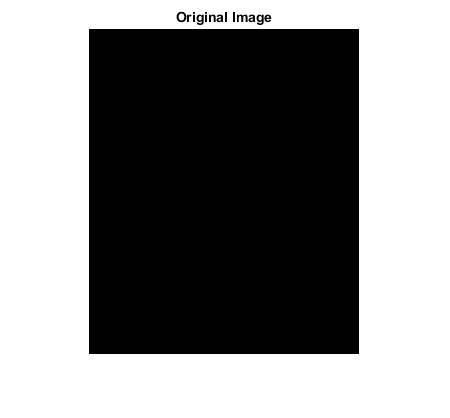

I = imread(fullFileName);

I = I(:,:,1);

num_pixels = nonzeros(I);


[rows, columns] = size(I(:,:));
    
ma_x = max(I(:))/10;
    
mi_n = min(I(:))/10;
            
divide = ma_x / mi_n;
    
normalImage = round(I ./ 10);
            
hist_mean = round(mean(nonzeros(normalImage)));

normalImage(normalImage < (2 * hist_mean) + int_thresh_ff) = 0;

normalImage(normalImage > 0) = 1;

im_thresh = mat2gray(normalImage);

num_pixels_I = nonzeros(im_thresh);

figure(1); 

imshow(im_thresh);

title('Original Image');

## Step 1a Sharpening the Image

threshold = 1;
fudgeFactor = 0.20;

BWs = edge(im_thresh,'sobel',(threshold * fudgeFactor));

se90 = strel('line',3,90);
se0 = strel('line',3,0);

BWsdil = imdilate(BWs, [se0,se90]);

BWdfill = imfill(BWsdil, 4, 'holes');

## Step 5 Smooth the Object and Remove Outliers

seD = strel('diamond',4);

BWfinal = imerode(BWdfill, seD);

[y, x] = ndgrid(1:size(BWfinal, 1), 1:size(BWfinal, 2));
centroid = mean([x(logical(BWfinal)), y(logical(BWfinal))]);


area = bwarea(BWfinal);

## Step 5 Outlining Image

BWoutline = bwperim(BWfinal, 4);

Segout = im_thresh;

Segout(BWoutline) = 0;

figure(7);
 
imshow(Segout);
 
title('Outlined Original Image');

## Step 6 Identifying Projections

se = strel('disk',disk_size);

closeBW = imopen(BWfinal,se);

closeBWoutline = bwperim(closeBW, 4);

Segout_2 = BWfinal;

Segout_2(closeBWoutline) = 0;

figure(8);

imshow(Segout_2);

title('Cell Body from Original Image');

no_cell_body = BWfinal - closeBW;

figure(9);

imshow(no_cell_body);

title('Original Image with no cell body');

%Connecting objects in the image
cc_pro = bwconncomp(no_cell_body, 4);

%cc_pro = bwareaopen(cc_pro,2);
            
cc_pro_area = regionprops(cc_pro, 'Area');
            
cc_pro_area = (cell2mat(struct2cell(cc_pro_area)))';
            
pro_area_mat = mean(cc_pro_area, 'all');
            
avg_area = round(pro_area_mat);
            
no_cell_body_reduc = bwareaopen(no_cell_body,avg_area + pro_thresh_ff);
            
cc_pro = bwconncomp(no_cell_body_reduc, 4);                          
        
%MATLAB labelling the image
pro_labels = labelmatrix(cc_pro);
            
pro_labels = double(pro_labels);        
        
figure(10);

imshow(pro_labels);

[pro_labels, num_pro] = bwlabel(pro_labels);

num_pro = num_pro;

proSpec = 'The number of cellular projections are %4.2f';

fprintf(proSpec,num_pro);

## Extra Step Displaing All Images

%figure(9);

%subplot(2,3,1), imshow(I)

%subplot(2,3,2), imshow(II)

%subplot(2,3,3), imshow(BWs)

%subplot(2,3,4), imshow(BWsdil)

%subplot(2,3,5), imshow(BWfinal)

%subplot(2,3,6), imshow(Segout)